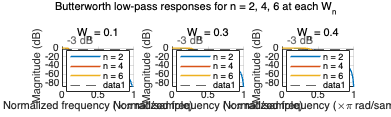

%% Problem 2: Butterworth LPF design and frequency responses
clear; clc; close all;

nValues = [2, 4, 6];
WnValues = [0.1, 0.3, 0.4];
Nfft = 2048;

figure('Name', 'Problem 2 - Butterworth Low-pass', 'Color', 'w', 'Position', [80 120 1200 360]);

for i = 1:numel(WnValues)
    Wn = WnValues(i);
    subplot(1, 3, i);
    hold on;
    grid on;

    for j = 1:numel(nValues)
        n = nValues(j);
        [b, a] = butter(n, Wn, 'low');
        [h, w] = freqz(b, a, Nfft);

        magDb = 20 * log10(max(abs(h), 1e-8));
        plot(w / pi, magDb, 'LineWidth', 1.4, 'DisplayName', sprintf('n = %d', n));
    end

    yline(-3, '--', '-3 dB', 'LabelHorizontalAlignment', 'left');
    xlabel('Normalized frequency (\times\pi rad/sample)');
    ylabel('Magnitude (dB)');
    title(sprintf('W_n = %.1f', Wn));
    xlim([0 1]);
    ylim([-90 5]);
    legend('Location', 'southwest');
    hold off;
end

sgtitle('Butterworth low-pass responses for n = 2, 4, 6 at each W_n');


% Print one set of coefficients for report copy/paste.
fprintf('Example coefficients (n = 4, Wn = 0.3):\n');

Example coefficients (n = 4, Wn = 0.3):


[bEx, aEx] = butter(4, 0.3, 'low');
disp('b ='); disp(bEx);

b =
    0.0186    0.0743    0.1114    0.0743    0.0186



disp('a ='); disp(aEx);

a =
    1.0000   -1.5704    1.2756   -0.4844    0.0762




fprintf(['\nProblem 2 done.\n', ...
         'For filterDesigner/fdatool task: open MATLAB app "Filter Designer",\n', ...
         'choose IIR-Butterworth, Lowpass, set order and Wn, then export coefficients.\n']);


Problem 2 done.
For filterDesigner/fdatool task: open MATLAB app "Filter Designer",
choose IIR-Butterworth, Lowpass, set order and Wn, then export coefficients.
